# Track Generator

we input both x and y coordinates, the scripts then saves a interpolated and smoothed versioned of the provided path in a .mat file.

n_points = 50

n_points = 50

% randomly generate 20 points in the 2D
points = rand(20, 2)*100 - 50;

% Perform Convex Hull
k = convhull(points(:, 1), points(:, 2));

spline_param = linspace(0,2*pi,length(k)); 
spl_points = [points(k,1), points(k,2)];

pp = spline(spline_param, spl_points');
yy = ppval(pp, linspace(0,2*pi,n_points));

random_path = yy';

random_path =    46.1898   12.2055
   45.6372   14.6221
   44.5921   17.1648
   43.0651   19.7892
   41.0667   22.4505
   38.6074   25.1043
   35.6979   27.7059
   32.3487   30.2107
   28.5704   32.5742
   24.3735   34.7517


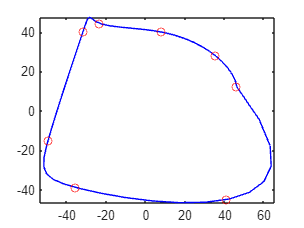


plot(random_path(:, 1),random_path(:, 2),'-b', spl_points(:,1), spl_points(:, 2),'or')
axis equal

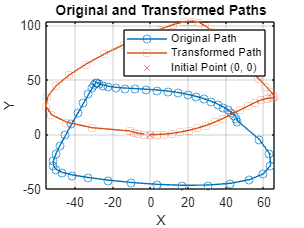

transformedPath = transformPath(random_path);

% Display the original and transformed paths
figure;
plot(random_path(:, 1), random_path(:, 2), 'o-', 'DisplayName', 'Original Path');
hold on;
plot(transformedPath(:, 1), transformedPath(:, 2), 's-', 'DisplayName', 'Transformed Path');
plot(0, 0, 'rx', 'DisplayName', 'Initial Point (0, 0)');
legend;
grid on;
xlabel('X');
ylabel('Y');
title('Original and Transformed Paths');
hold off

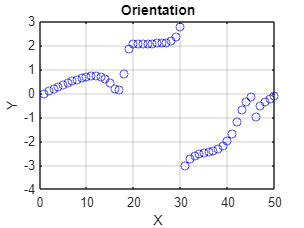

% Calculate the orientation reference for each point
orientationReference = atan2(transformedPath(2:end, 2) - transformedPath(1:end-1, 2), transformedPath(2:end, 1) - transformedPath(1:end-1, 1));
orientationReference(n_points) = atan2(transformedPath(1, 2) - transformedPath(n_points, 2), transformedPath(1, 1) - transformedPath(n_points, 1));

plot(1:length(orientationReference), orientationReference,"bo")
title("Orientation")
xlabel("X")
ylabel("Y")
grid on

track_info = zeros(n_points, 3)

track_info =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



track_info(:, 1) = transformedPath(:, 1)

track_info =          0         0         0
    3.6181         0         0
    7.5039         0         0
   11.6176         0         0
   15.9193         0         0
   20.3692         0         0
   24.9272         0         0
   29.5536         0         0
   34.2085         0         0
   38.8486         0         0


track_info(:, 2) = transformedPath(:, 2)

track_info =          0         0         0
    3.6181   -0.0000         0
    7.5039    0.3657         0
   11.6176    1.1197         0
   15.9193    2.2846         0
   20.3692    3.8828         0
   24.9272    5.9371         0
   29.5536    8.4699         0
   34.2085   11.5037         0
   38.8486   15.0399         0


track_info(:, 3) = orientationReference

track_info =          0         0   -0.0000
    3.6181   -0.0000    0.0938
    7.5039    0.3657    0.1813
   11.6176    1.1197    0.2644
   15.9193    2.2846    0.3448
   20.3692    3.8828    0.4234
   24.9272    5.9371    0.5009
   29.5536    8.4699    0.5776
   34.2085   11.5037    0.6512
   38.8486   15.0399    0.7024


% save track coordinates in mat file
save("track.mat","track_info")

function transformedPath = transformPath(inputPath)
    % Randomly select the initial point
    initialPointIndex = randi(size(inputPath, 1));
    initialPoint = inputPath(initialPointIndex, :);

    % Translate all points to align the initial point to (0, 0)
    translatedPath = inputPath - initialPoint;

    % Rotate all points to align the second point with y-coordinate equal to 0
    angle = atan2(translatedPath(initialPointIndex + 1, 2), translatedPath(initialPointIndex + 1, 1));
    rotationMatrix = [cos(-angle), -sin(-angle); sin(-angle), cos(-angle)];
    rotatedPath = (rotationMatrix * translatedPath')';

    % Reorder the path points with the zero-index point as the first point
    reorderedPath = circshift(rotatedPath, [1 - initialPointIndex, 0]);

    % Output the transformed path
    transformedPath = reorderedPath;
end